# Create Desired Absorption Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

[whaley,fs] = audioread("./data/whalesound.wav");
n = numel(whaley);
fr = (0:n-1)*(fs/n);
fr = fr(1:n/2+1);

## Task 1

The function `absorption` was downloaded from the [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/28653-acoustic-absorption-in-seawater) and was simplified to use as a helper function for this module. It returns the water absorption value for a vector of frequencies.

`a` `=` `absorption``(``freq``)`

waterabs = absorption(fr);

## Task 2

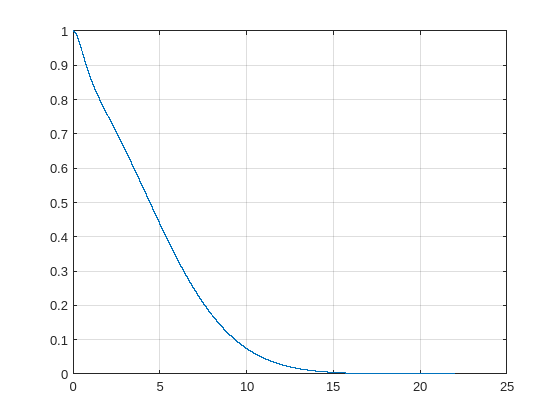

plot(fr/1000,waterabs)
grid on

% Calculating the absorption coefficent of seawater in dB / km
% CWJ for AOR Sept 2010

function [alpha] = absorption(freq,km)
    % Following Kinsler, et al "Fundamentals of Acoustics, Fourth Edition" p. 226-228.
    pH = 8; % pH
    S = 35; % salinity in ppt
    T = 5; % temperature in C
    Z = 0; % depth in km
    if nargin == 1
        km = 20;
    end
    
    f_1 = 780*exp(T/29);
    f_2 = 42000*exp(T/18);
    A = 0.083*(S/35)*exp(T/31 - Z/91 + 1.8*(pH-8));
    B = 22*(S/35)*exp(T/14-Z/6);
    C = 4.9E-10*exp(-T/26 - Z/25);
    boric_acid = A./(f_1^2+freq.^2); % contribution from boric acid
    MgSO4 = B./(f_2^2+freq.^2); % contribution from MgSO4
    hydrostatic = C; % contribution from hydrostatic pressure
    alpha = (boric_acid + MgSO4 + hydrostatic).*freq.^2;
    alpha = 10.^(-alpha*km/20); % convert from dB to linear
end